# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials and 0 textures.
Attribute processing: Identified 2 assets; parsed up to line 12


thisR.set('light','all','delete');

The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

thisLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',thisLight, 'add');
thisR.set('light',thisLight.name,'specscale',0.5);
thisR.set('light',thisLight.name,'spd',[0.5 0.4 0.2]);

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera, so that we are effectively rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

scene = piRender(thisR);

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t --delete /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/ ...
Done (0.73 sec)
USE Docker: docker --context remote-orange exec -it  pbrt-gpu-wandell18603 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/sphere.exr sphere.

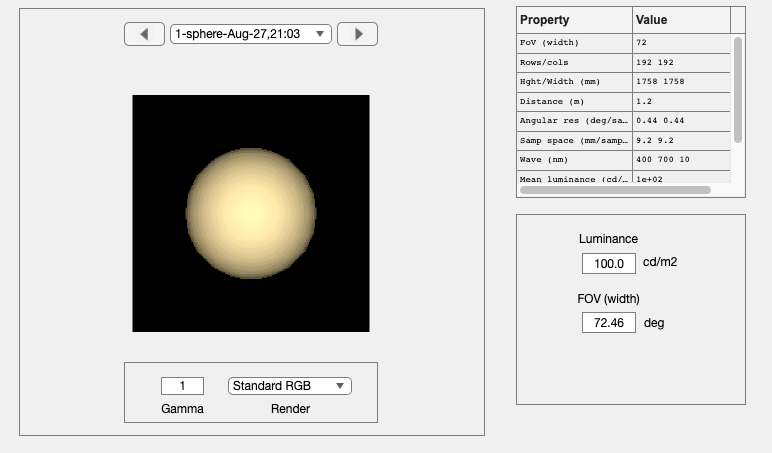

sceneWindow(scene);

dockerWrapper.getPrefs;



dockerWrapper defaults (getprefs('docker'))
________________

	gpuRendering		1
	localRender		0
	remoteResources		1
	renderContext		'remote-orange'
	remoteMachine		'orange.stanford.edu'
	remoteRoot		'/home/wandell'
	remoteImage		'digitalprodev/pbrt-v4-gpu-ampere-ti'
	whichGPU		1
	verbosity		1
	defaultContext		'default'
	localImage		''
	remoteUser		'wandell'
	localVolumePath		'/Users/wandell/Documents/MATLAB/iset3d-v4/local'
	localRoot		''
	remoteCPUImage		'digitalprodev/pbrt-v4-cpu'
	remoteImageTag		'latest'
	localImageName		'digitalprodev/pbrt-v4-gpu-ampere-mux'
	localImageTag		'latest'

Configured for rendering on orange.stanford.edu using a GPU.



[scene, result] = piRender(thisR);

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t --delete /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/ ...
Done (0.65 sec)
USE Docker: docker --context remote-orange exec -it  pbrt-gpu-wandell18603 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/sphere.exr sphere.

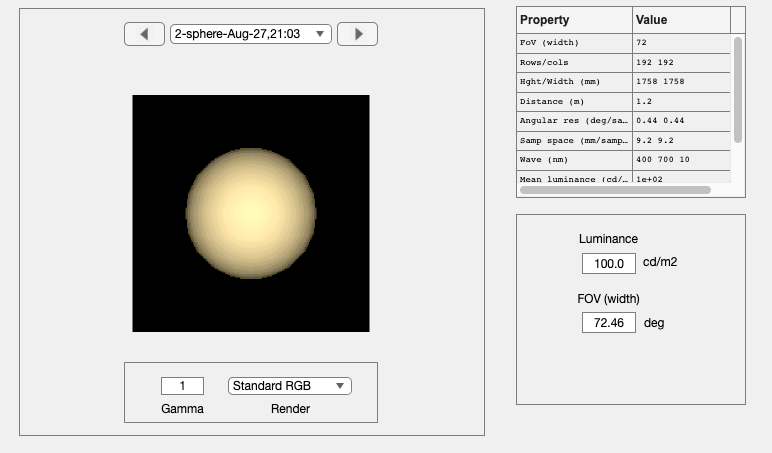

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

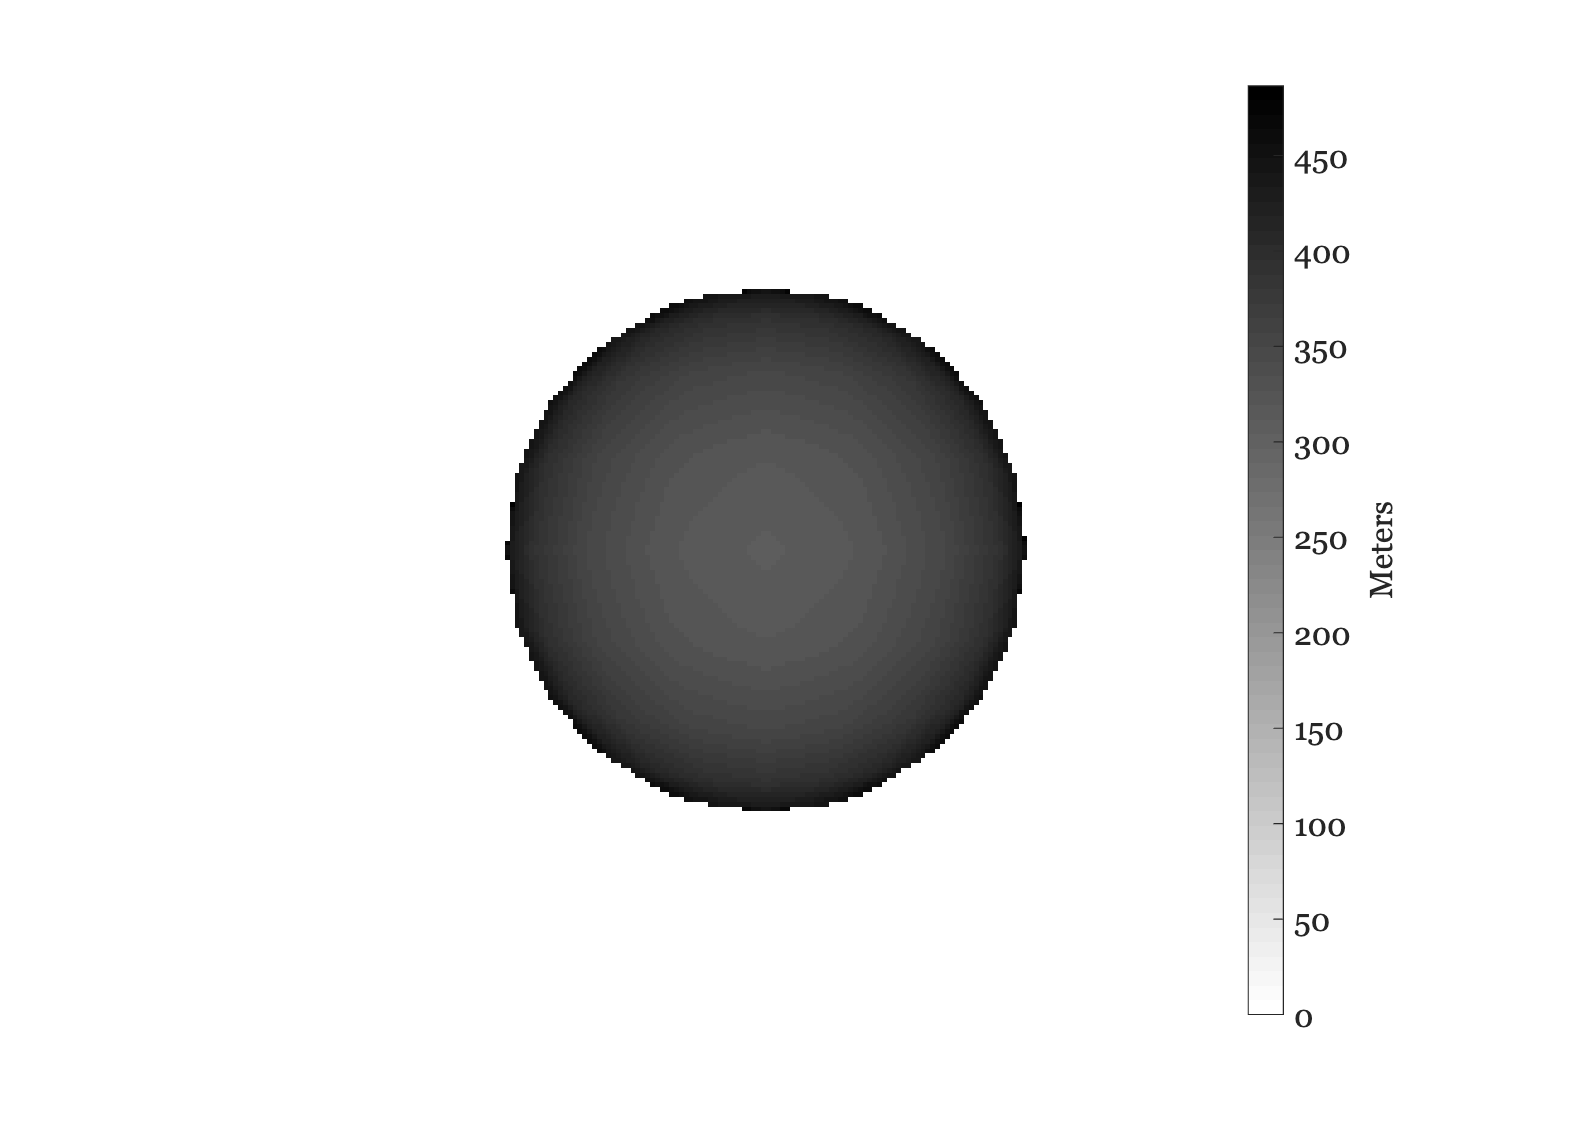

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

% Remove the light we added
thisR.set('light',thisLight.name, 'delete');

% Create a new version with a different color temperature
thisLight = piLightCreate('distant','type','distant',  'spd', 9000,  'cameracoordinate', true);
thisR.set('light',thisLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t --delete /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/ ...
Done (0.55 sec)
USE Docker: docker --context remote-orange exec -it  pbrt-gpu-wandell18603 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*}  && cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps ; cp -n -r lens/* /ISETResources/lens ; rm -rf lens ; ln -s /ISETResources/lens lens && pbrt --gpu --outfile renderings/sphere.exr sphere.

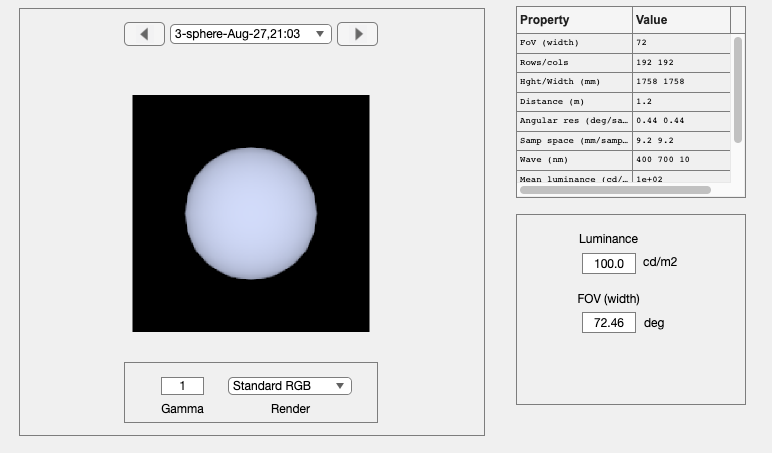

piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fname = fullfile(piRootPath,'data','scenes','teapot-set','TeaTime-converted.pbrt');
 
thisR  = piRead(fname);

Setting integrator to "path" with 5 bounces.
Read 6 materials and 1 textures.
Attribute processing: Identified 5 assets; parsed up to line 81


Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);

Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');


----- Summary of recipe: recipe

                      index        material            positions (m)               sizes (m)        
                      _____    ________________    _____________________    ________________________

    Cylinder.001_O      6      {'Stone'       }    {'6.39 5.47 16.50'  }    {'10.49 10.49 9.18'    }
    Cylinder.004_O     15      {'Stone'       }    {'-8.18 5.47 11.67' }    {'10.49 10.49 9.18'    }
    Plane_O            24      {'Material.008'}    {'1.37 0.00 -7.50'  }    {'143.94 128.10 114.17'}
    Cylinder.005_O     27      {'Stone'       }    {'-0.41 10.67 -9.39'}    {'20.47 29.42 19.97'   }

From [-6.52, 223.967285, 0.607015] to [-3.72, 124.006485, 0.575510] up [-1.00, -0.027995, 0.011207]


## Add a light

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t --delete /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime-converted/ wandell@orange.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime-converted/ ...


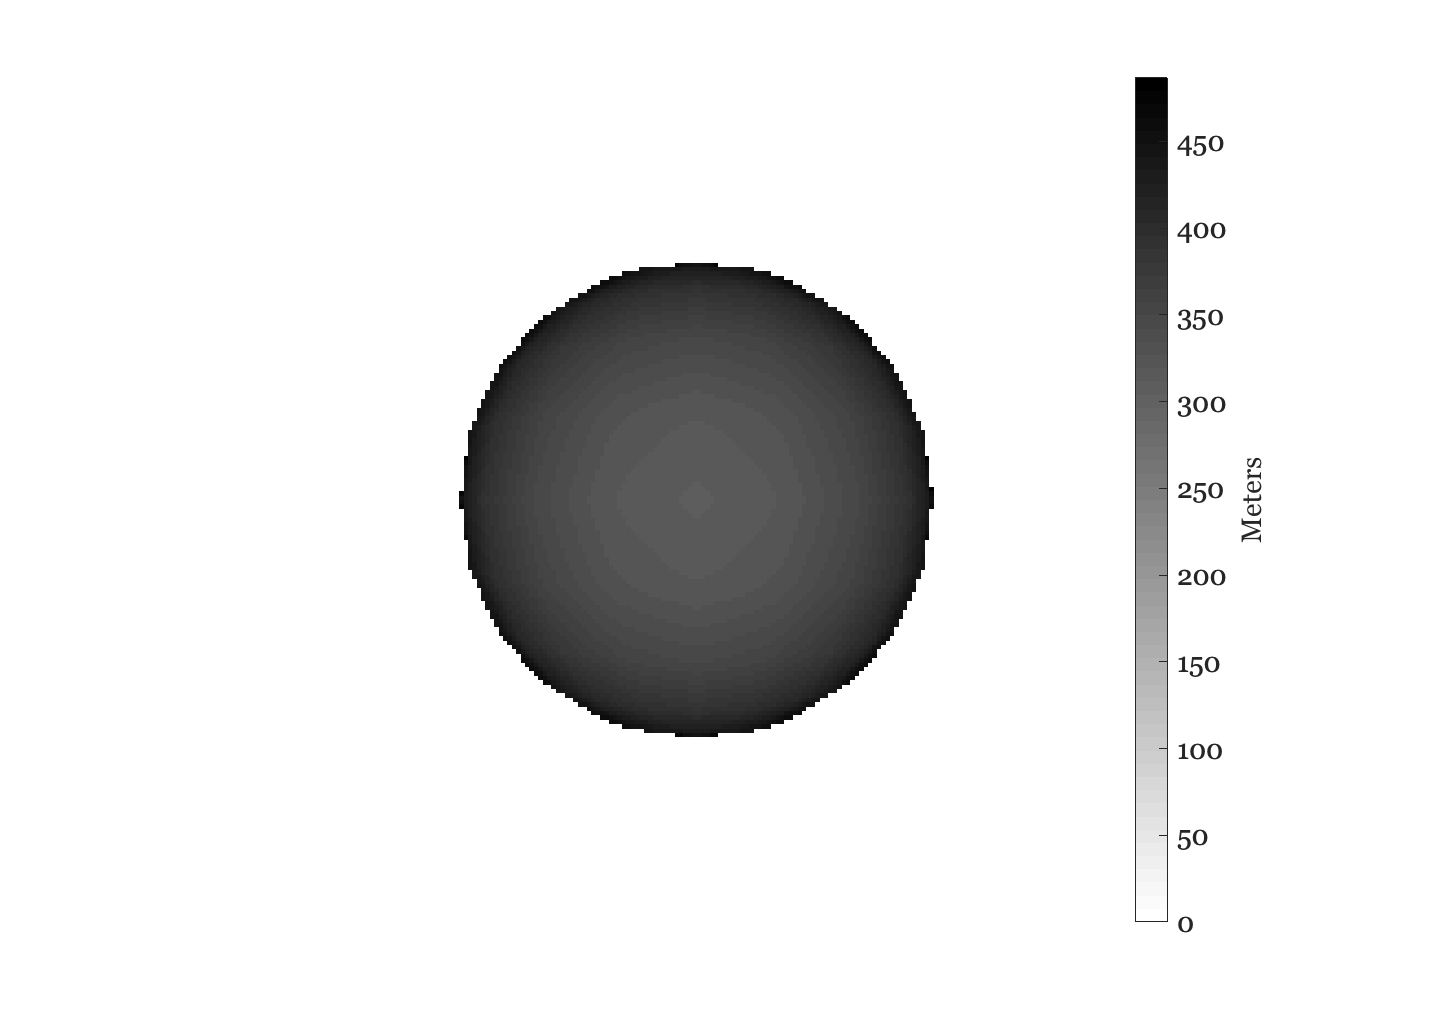

thisR.set('lights','all','delete');
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

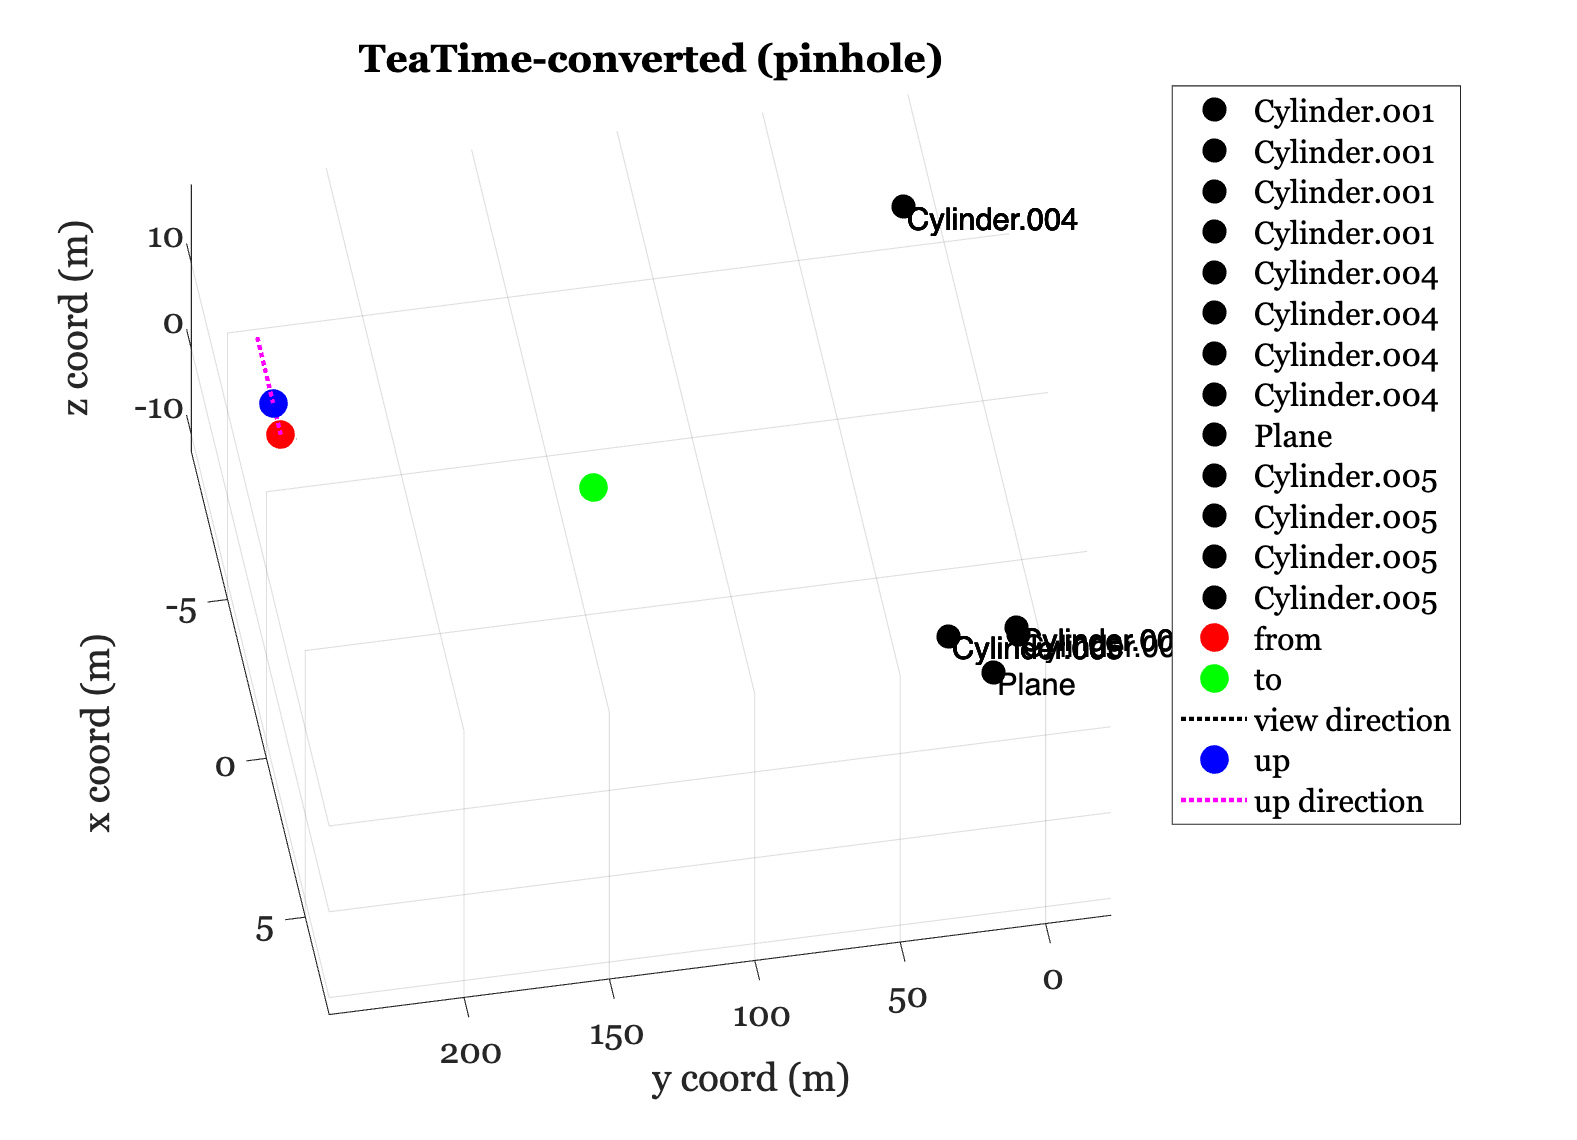

piAssetGeometry(thisR);view(-80,-65);